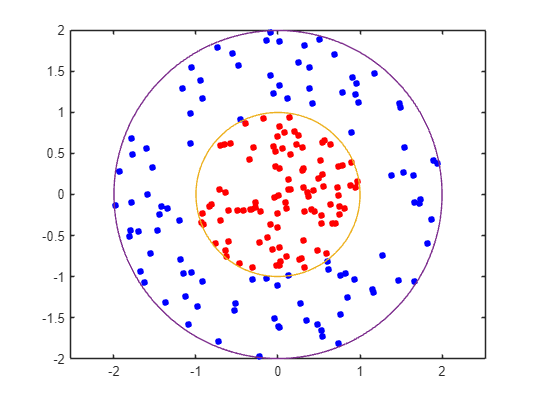

rng(1); % For reproducibility
r = sqrt(rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points

r2 = sqrt(3*rand(100,1)+1); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % Points

figure
plot(data1(:,1),data1(:,2),"r.","MarkerSize",15)
hold on
plot(data2(:,1),data2(:,2),"b.","MarkerSize",15)
fplot(@(t)sin(t),@(t)cos(t))
fplot(@(t)2*sin(t),@(t)2*cos(t))
axis equal
hold off


data3 = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

% Train the SVM classifier
cl = fitcsvm(data3,theclass,"KernelFunction","rbf", ...
    "BoxConstraint",Inf,"ClassNames",[-1 1]);

% Predict scores over the grid
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(data3(:,1)):d:max(data3(:,1)), ...
    min(data3(:,2)):d:max(data3(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);

% Plot the data and the decision boundary
figure
h(1:2) = gscatter(data3(:,1),data3(:,2),theclass,"rb",".");
hold on
fplot(@(t)sin(t),@(t)cos(t))

Holaaaaaaa

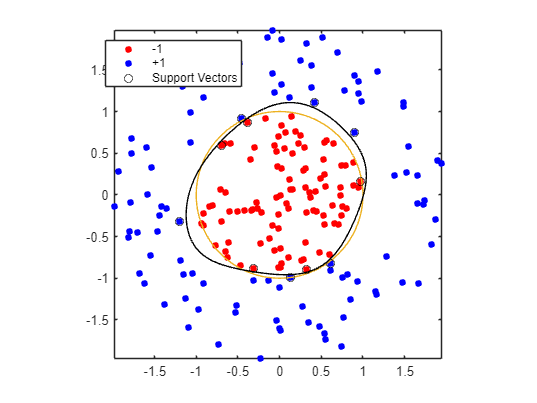

h(3) = plot(data3(cl.IsSupportVector,1),data3(cl.IsSupportVector,2),"ko");
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],"k")
legend(h,["-1","+1","Support Vectors"])
axis equal
hold off

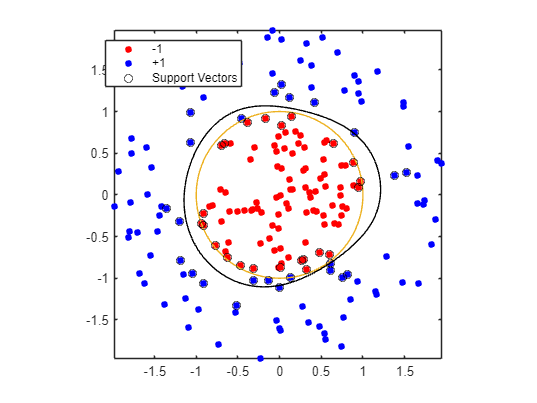


cl2 = fitcsvm(data3,theclass,"KernelFunction","rbf");
[~,scores2] = predict(cl2,xGrid);

figure
h(1:2) = gscatter(data3(:,1),data3(:,2),theclass,"rb",".");
hold on
fplot(@(t)sin(t),@(t)cos(t))
h(3) = plot(data3(cl2.IsSupportVector,1),data3(cl2.IsSupportVector,2),"ko");
contour(x1Grid,x2Grid,reshape(scores2(:,2),size(x1Grid)),[0 0],"k")
legend(h,["-1","+1","Support Vectors"])
axis equal
hold off

hiuahsudbsabdhasbhfbae